# Class 6 Problem 1 Derivative Pricing KO Using PDEs

## Problem

Solving KO option using PDE

- Black-Scholes

- Random Walks

- Trinomial Trees - Grid Solutions

- PDE - Grid Solutions

### 0. Download Option Prices for KO

At 10:44am KO's [price](https://ca.finance.yahoo.com/quote/KO/options?date=1702598400&p=KO&straddle=false) was given as $53.40. A snap of the call option chain is below. 

We will focus on the $55 dollar level for the exercise.

The implied volatility for the $55 strike call was 18.3% and for the $55 strike put was 22.0%.

C_MKT = 1.03;
P_MKT = 2.62;

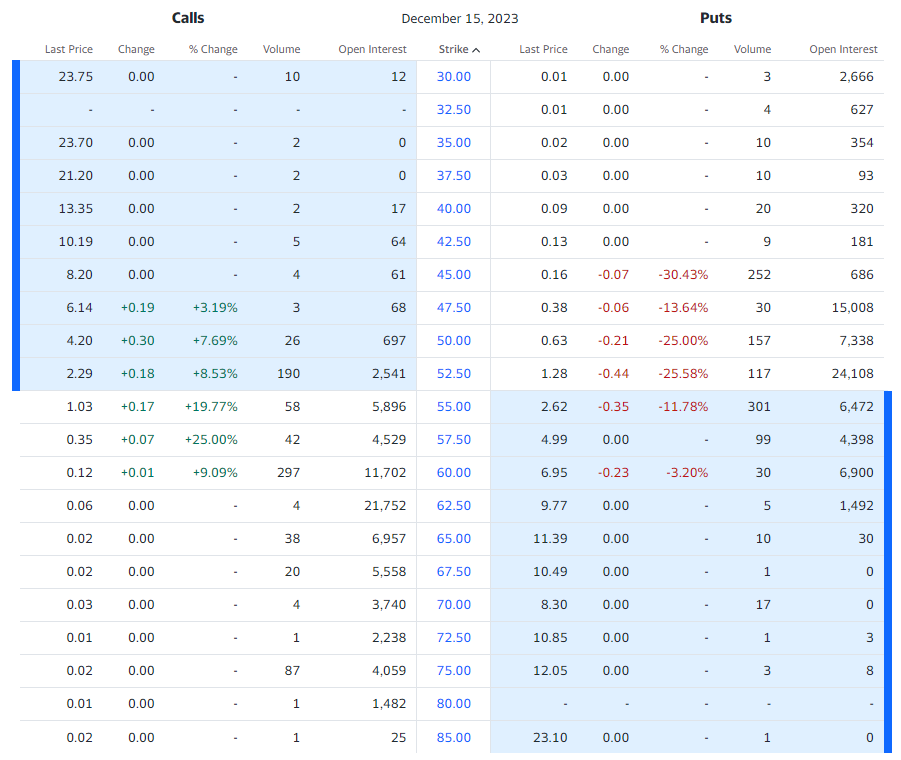

Their dividend data is as follows:

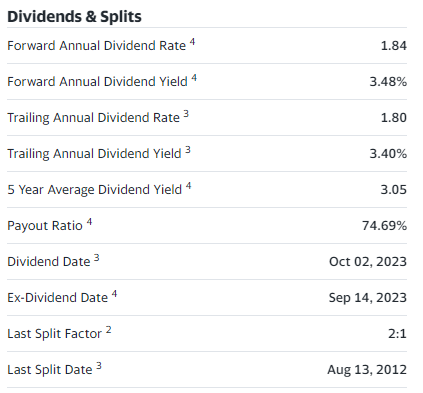

% Download data for Coke
startDate = '2018-10-16';
endDate = '2023-10-14';
KO_data = py.yfinance.download('KO', pyargs('start', startDate, 'end', endDate, 'interval', '1d'));


[*********************100%***********************]  1 of 1 completed


TTKO = table(KO_data);
TTKO = renamevars(TTKO, ["Close"], ["Price"]);
TTKO = removevars(TTKO,["Open","High","Low","Adj Close","Volume"])

TTKO = 1257×2 table
       Date        Price
    ___________    _____

    16-Oct-2018    45.49
    17-Oct-2018    45.86
    18-Oct-2018    45.61
    19-Oct-2018    46.33
    22-Oct-2018    45.97
    23-Oct-2018    46.36
    24-Oct-2018    46.73
    25-Oct-2018    46.51
    26-Oct-2018    45.92
    29-Oct-2018    46.46
    30-Oct-2018    47.63
    31-Oct-2018    47.88
    01-Nov-2018    47.74
    02-Nov-2018       48
    05-Nov-2018    48.69
    06-Nov-2018    49.11


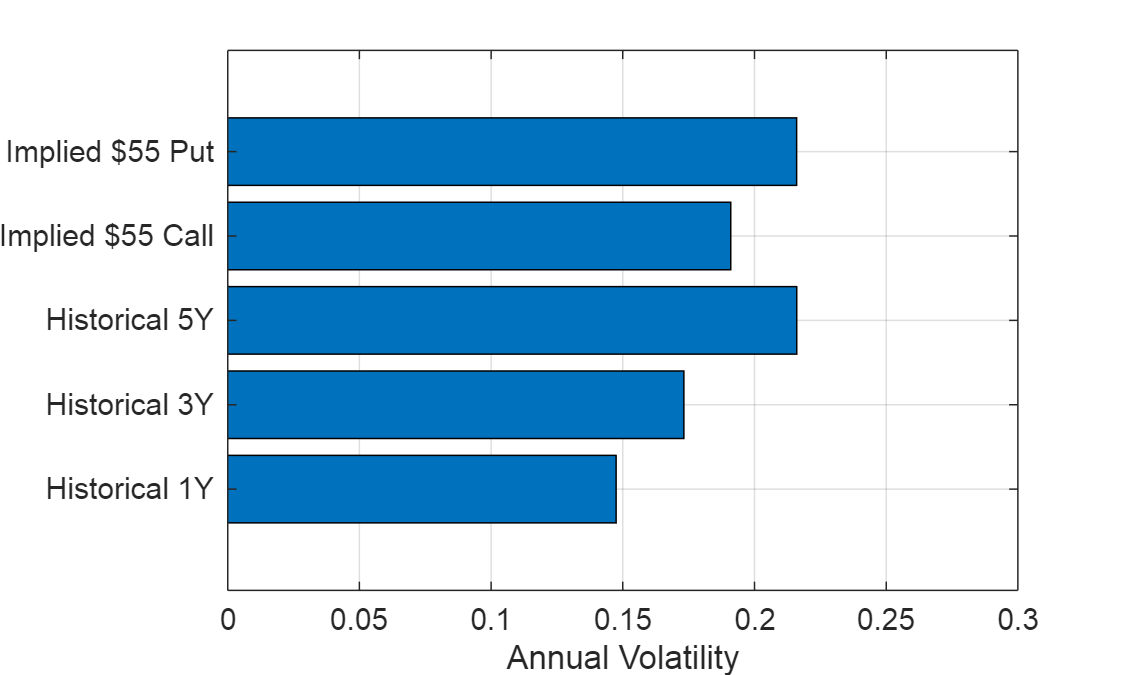

% What is the historical volatility of the stock over different time frames
tHistorical = datenum(TTKO.Date);
SHistorical = TTKO.Price;
rKO = diff(SHistorical) ./ SHistorical(1:end-1);
 
sigmaHist1YEAR = std(rKO(end-252+1:end)) * sqrt(252);
sigmaHist3YEAR = std(rKO(end-2*252+1:end)) * sqrt(252);
sigmaHist5YEAR = std(rKO(1:end)) * sqrt(252);
 
sigma55Call = 0.191; % from the option chain in Yahoo! 20.6
sigma55Put = 0.216; % from the option chain in Yahoo!
 
% Results and Output
figure()
set(gcf,'Position',[0,0,500,300])
 
barh([sigmaHist1YEAR, sigmaHist3YEAR, sigmaHist5YEAR, sigma55Call, sigma55Put])
 
xlabel('Annual Volatility')
set(gca,'YTickLabels', {'Historical 1Y', ...
                        'Historical 3Y', ...
                        'Historical 5Y',... 
                        'Implied $55 Call', ...
                        'Implied $55 Put'})
xlim([0 0.3])
box on
grid on

### 1. Black-Scholes-Merton Model

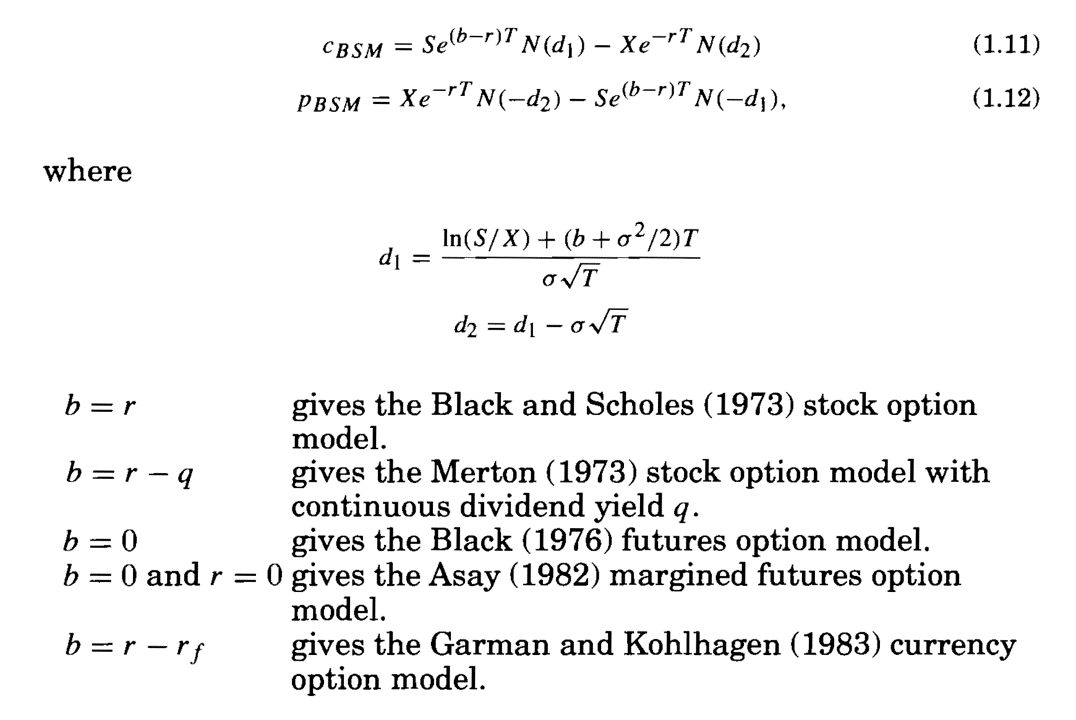

% Basic Market Observations
 
So = SHistorical(end); %53.40; % Current stock price
K = 55; % Strike price for example
r = 0.0531; % SOFR rate of 5.31%
%sigma = 0.1920; % 19.2% from the option chain on Yahoo!
q = 0.018; % trailing annual dividend yield
 
% Prepping the Calculation
 
% For December 15, 2002 we calculate T in years
To = datenum(2023,10,16);
TExpiration = datenum(2023,12,15);
TDays = (TExpiration - To); % in days
T = (TExpiration - To) / 365; % in years
 
% The "known" part
b = r - q;
 
% Calculate Black Scholes price for the option
d1 = (log(So/K) + (b + sigma55Call^2 / 2)*T) / (sigma55Call*sqrt(T));
d2 = d1 - sigma55Call * sqrt(T);
 
C_BSM = So * exp((b-r)*T) * normcdf(d1) - K * exp(-r*T) * normcdf(d2)

C_BSM = 0.9134

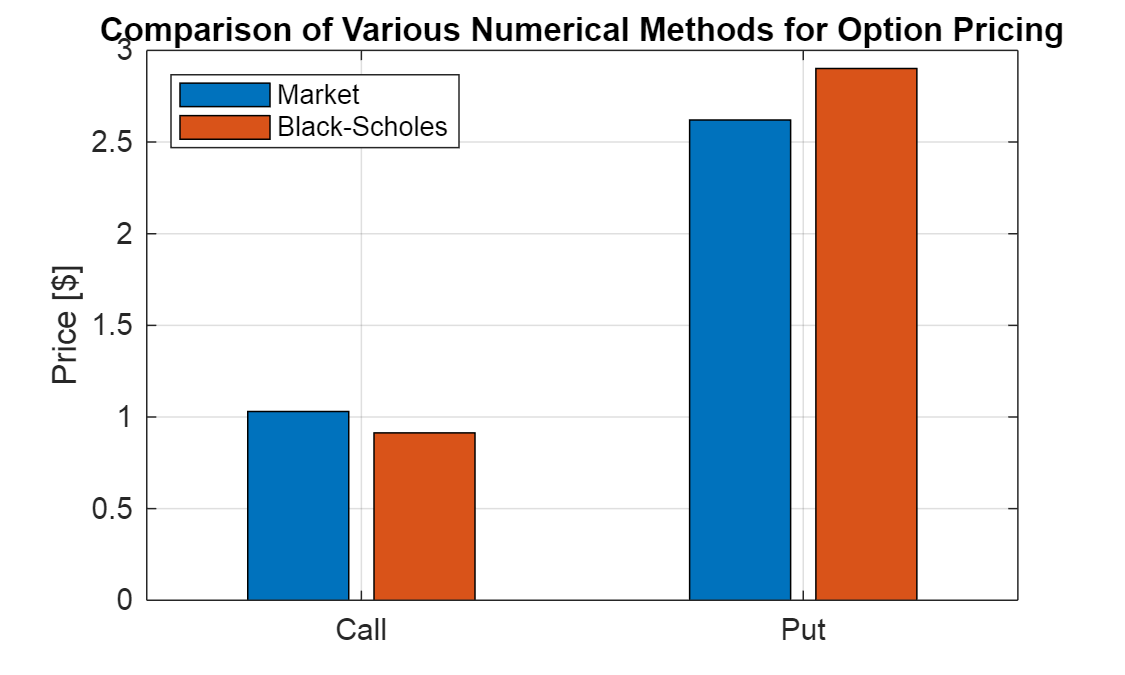

d1 = (log(So/K) + (b + sigma55Put^2 / 2)*T) / (sigma55Put*sqrt(T));
d2 = d1 - sigma55Put * sqrt(T);
 
P_BSM = K * exp(-r*T) * normcdf(-d2) - So * exp((b-r)*T) * normcdf(-d1);
 
% Results and Output
figure()
set(gcf,'Position',[0,0,500,300])
 
bar([C_MKT, C_BSM; P_MKT ,P_BSM])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Price [$]')
legend({'Market','Black-Scholes'}, 'location', 'northwest')
 
%xlabel('Annual Volatility')
set(gca,'XTickLabels', {'Call','Put'})
box on
grid on

### 2. Random Walk

Now we'll calculate the same values for the call option using the random walk model we've already developed.

% Define Extent of Walk and Number of Repititions
NTrials = 1000;
NSteps = TDays;
 
% Generate Normal Random Numbers
U = rand(NSteps, NTrials);
Z = norminv(U);
 
% Estimate RW Param
sigmaRwDays = sigma55Call / sqrt(365);
bRwDays = b / 365; % risk-neutral drift including dividend yield
dt = 1; % for 60 days
 
% The Geometric Random Walk ... we only need the last point for a European option, so this is just for continuity ... 
S_RW = So * cumprod(1 + bRwDays * dt + sigmaRwDays * sqrt(dt) * Z);
 
% For those of you who can't talk matrix yet :-)
% S_RW = zeros(size(U));
% S_RW(1,:) = So;
% for i = 2:NSteps
%     S_RW(i,:) = S_RW(i-1,:) .* (1 + (bRwDays/365) * dt + sigmaRwDays * Z(i,:) * sqrt(dt));
% end% for i
 
% Calculate value of the Call option
C_RW_Expiration = max(S_RW(end,:)-55,0);
PriceExp = 0:1:10;
CountExp = hist(C_RW_Expiration, PriceExp);
ProbExp = CountExp / NTrials;
 
C_RW = PriceExp * ProbExp' % expected value of the option price

C_RW = 0.8600

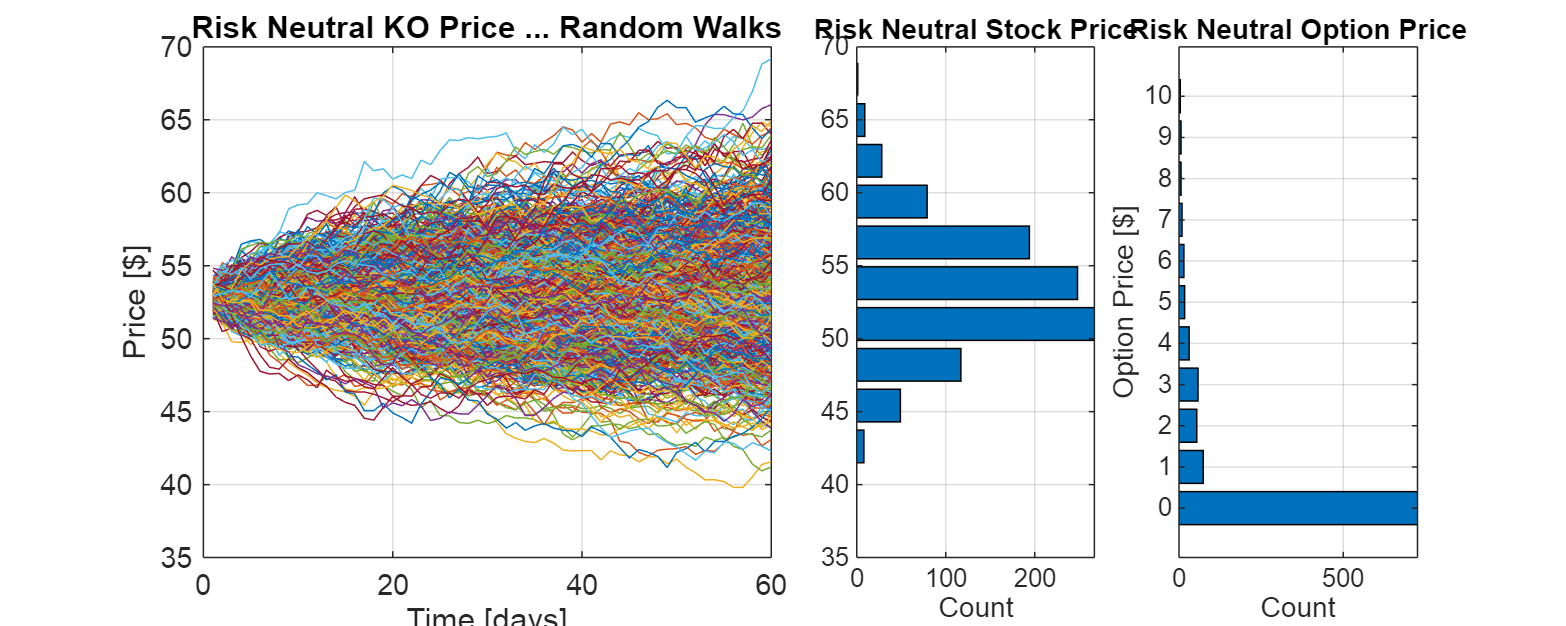


% Results and Graphs
figure()
set(gcf, 'Position', [0 0 1000 400])
 
% Graph the random walks
subplot(1,4,[1,2])
plot(S_RW)
title('Risk Neutral KO Price ... Random Walks')
xlabel('Time [days]')
ylabel('Price [$]')
ylim([35,70])
grid on
 
% Graph KO price at expiration
subplot(1,4,3)
 
[fBin,SBin] = hist(S_RW(end,:),10);
 
barh(SBin, fBin)
ylim([35,70])
grid on
title('Risk Neutral Stock Price')
xlabel('Count')
 
% Graph option price at expiration
subplot(1,4,4)
 
 
barh(PriceExp, CountExp)
title('Risk Neutral Option Price')
grid on
xlabel('Count')
ylabel('Option Price [$]')

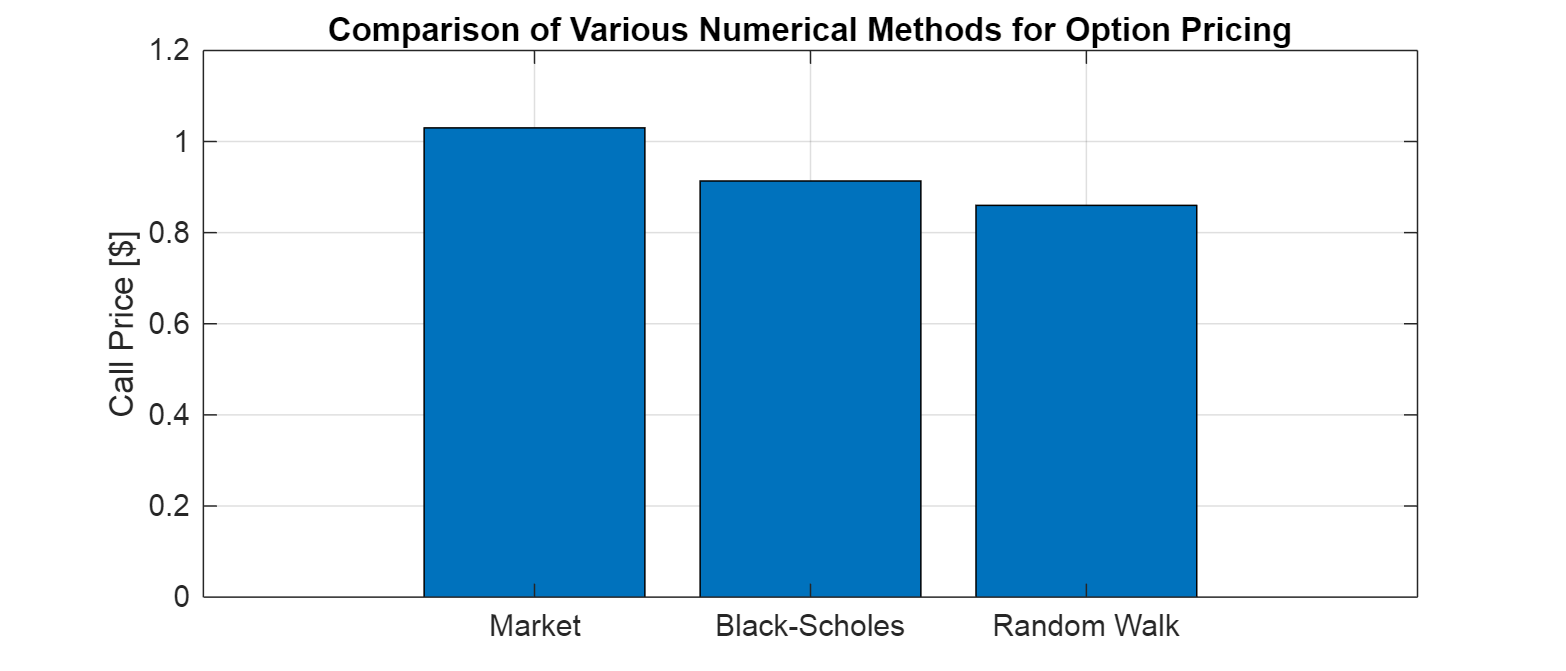


% Update on call option price by various methods
figure()
set(gcf,'Position',[0,0,700,300])
 
bar([C_MKT, C_BSM, C_RW])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Call Price [$]')
set(gca, 'XTickLabels', {'Market','Black-Scholes','Random Walk'})
 
box on
grid on

### 3. Trinomial Trees - Grid Method

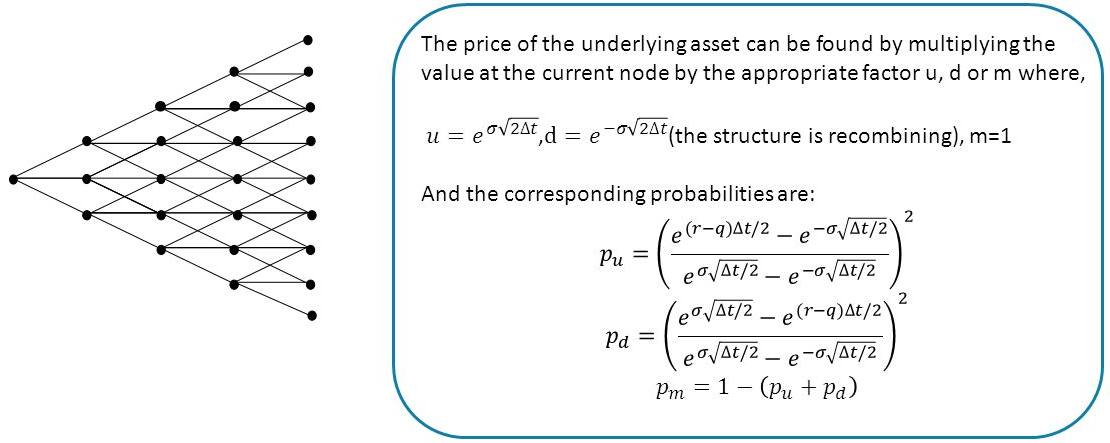

% Parameters for the Trinomial Tree
 
u = exp(sigmaRwDays*sqrt(2*dt));
d = exp(-sigmaRwDays*sqrt(2*dt));
m = 1;
 
numUp = exp(bRwDays * dt/2) - exp(-sigmaRwDays * sqrt(dt/2));
numDn = exp(sigmaRwDays * sqrt(dt/2)) - exp(bRwDays * dt/2);
den = exp(sigmaRwDays * sqrt(dt/2)) - exp(-sigmaRwDays * sqrt(dt/2));
 
pu = (numUp/den)^2;
pd = (-numDn/den)^2;
pm = 1 - (pu + pd);
 
 
% The Stock Tree on the Grid
TriGridHeight = 2 * NSteps - 1;
TriGridWidth = NSteps;
 
STriGrid = NaN(TriGridHeight, TriGridWidth);
 
TAxis = 1:NSteps;
SAxis = zeros(TriGridHeight,1);
 
for i = 1:TriGridHeight
    
    if i < TriGridHeight / 2
       SAxis(i) = So * d ^ (floor(TriGridHeight / 2) - i + 1);
    elseif i > TriGridHeight / 2 + 1
       SAxis(i) = So * u ^ (i - ceil(TriGridHeight / 2));
    elseif i == NSteps
       SAxis(i) = So;
    end%if
 
end%for i
 
 
% Fill in the Trinomial Tree in the grid
for j = 1:NSteps
 
    IBeg = NSteps - j + 1;
    IEnd = NSteps + j - 1;
    I = IBeg:IEnd;
 
    STriGrid(I,j) = SAxis(I);
 
end%for i
 
 
%%% Core Routine Starts here
 
% Determine the option Value ... bit more detailed here
VIntrinsic = max(STriGrid - 55, 0);
VEuro = NaN(size(STriGrid));
VAmer = NaN(size(STriGrid));
 
% Backward Induction
for j = NSteps:-1:1
 
    IBeg = NSteps - j + 1;
    IEnd = NSteps + j - 1;
    I = IBeg:IEnd;
 
    for i = 1:length(I)
 
        IntrinsicValue = VIntrinsic(I(i),j);
 
        if j == NSteps
    
            % Option prices at maturity are just Intrinsic Values
            VEuro(I(i), j) = IntrinsicValue;
            VAmer(I(i), j) = IntrinsicValue;
 
        else
 
            % The Backward Induction Algorithm
 
            VEuro(I(i), j) = exp(-bRwDays*dt) * (pu * VEuro(I(i)+1, j+1) + ...
                                                 pm * VEuro(I(i),   j+1) + ...
                                                 pd * VEuro(I(i)-1, j+1) );
 
            VAmer(I(i), j) = max(IntrinsicValue, exp(-bRwDays*dt) * (pu * VAmer(I(i)+1, j+1) + ...
                                                                     pm * VAmer(I(i),   j+1) + ...
                                                                     pd * VAmer(I(i)-1, j+1) ) );
        end%if
 
    end%for i
 
end%for j
 
VIntrinsic(NSteps,1)

ans = 0


C_TRI_EURO = VEuro(NSteps,1)

C_TRI_EURO = 0.9028

C_TRI_AMER = VAmer(NSteps,1)

C_TRI_AMER = 0.9028

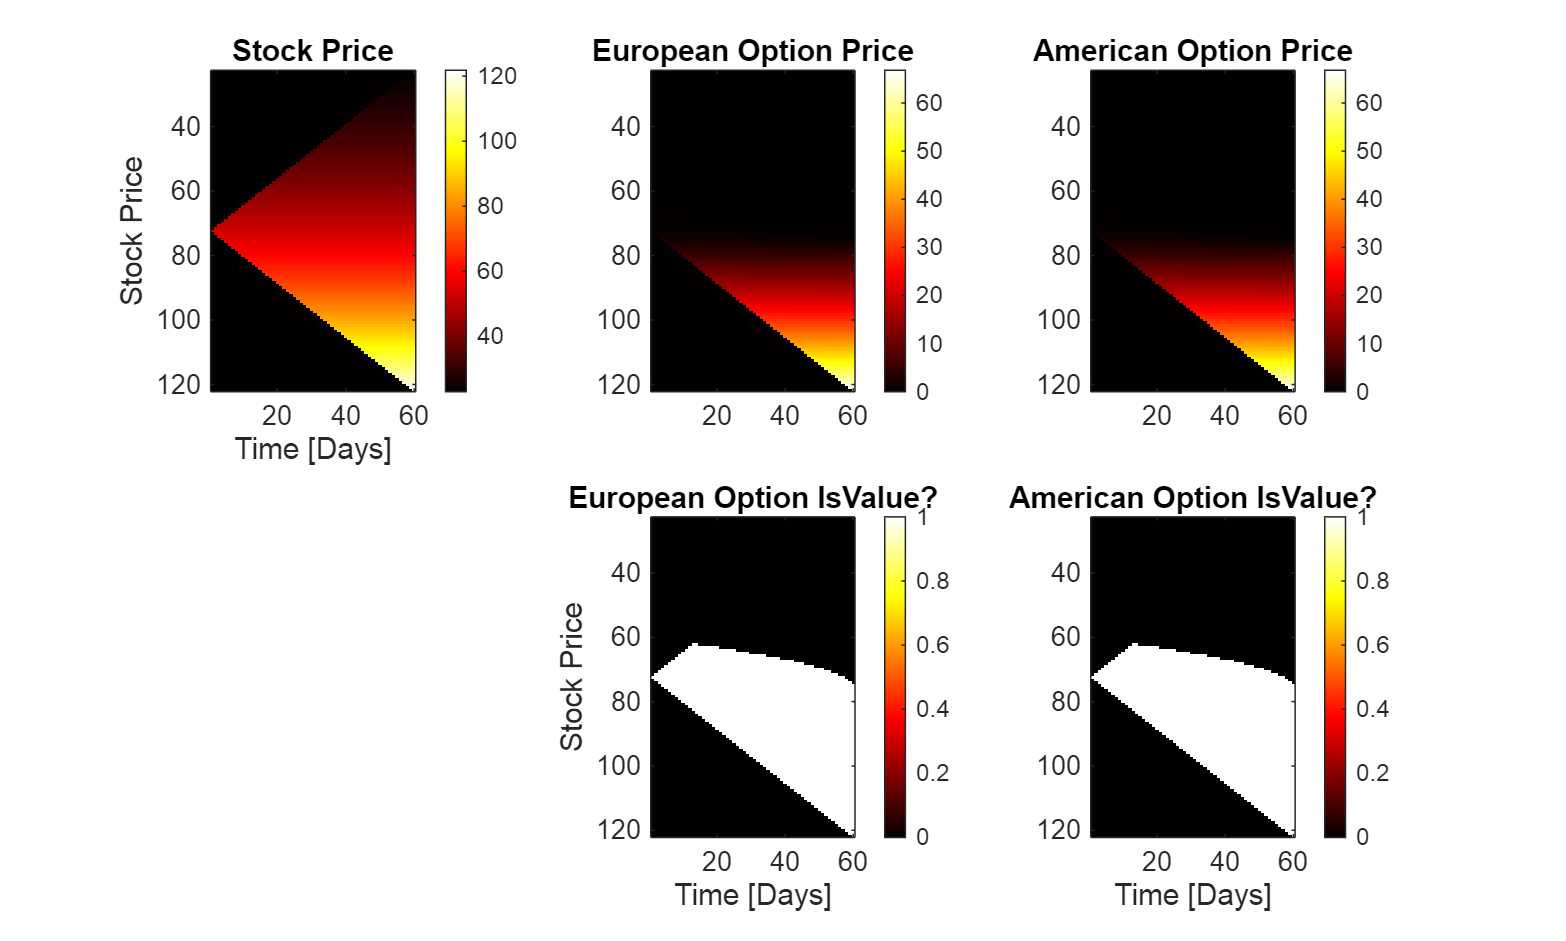


figure()
set(gcf, 'Position', [0,0,1000,600])
 
colormap(hot)
 
subplot(2,3,1)
imagesc(TAxis, SAxis, STriGrid)
colorbar
title('Stock Price')
ylabel('Stock Price')
xlabel('Time [Days]')
 
subplot(2,3,2)
imagesc(TAxis, SAxis, VEuro)
colorbar
title('European Option Price')
 
subplot(2,3,3)
nonzeroVAmer = zeros(size(VAmer));
nonzeroVAmer(VAmer > 0.001) = 1;
imagesc(TAxis, SAxis, VAmer)
colorbar
title('American Option Price')
 
 
subplot(2,3,5)
nonzeroVEuro = zeros(size(VEuro));
nonzeroVEuro(VEuro > 0.001) = 1;
imagesc(TAxis, SAxis, nonzeroVEuro)
colorbar
title('European Option IsValue?')
ylabel('Stock Price')
xlabel('Time [Days]')
 
subplot(2,3,6)
nonzeroVAmer = zeros(size(VAmer));
nonzeroVAmer(VAmer > 0.001) = 1;
imagesc(TAxis, SAxis, nonzeroVAmer)
colorbar
title('American Option IsValue?')
xlabel('Time [Days]')

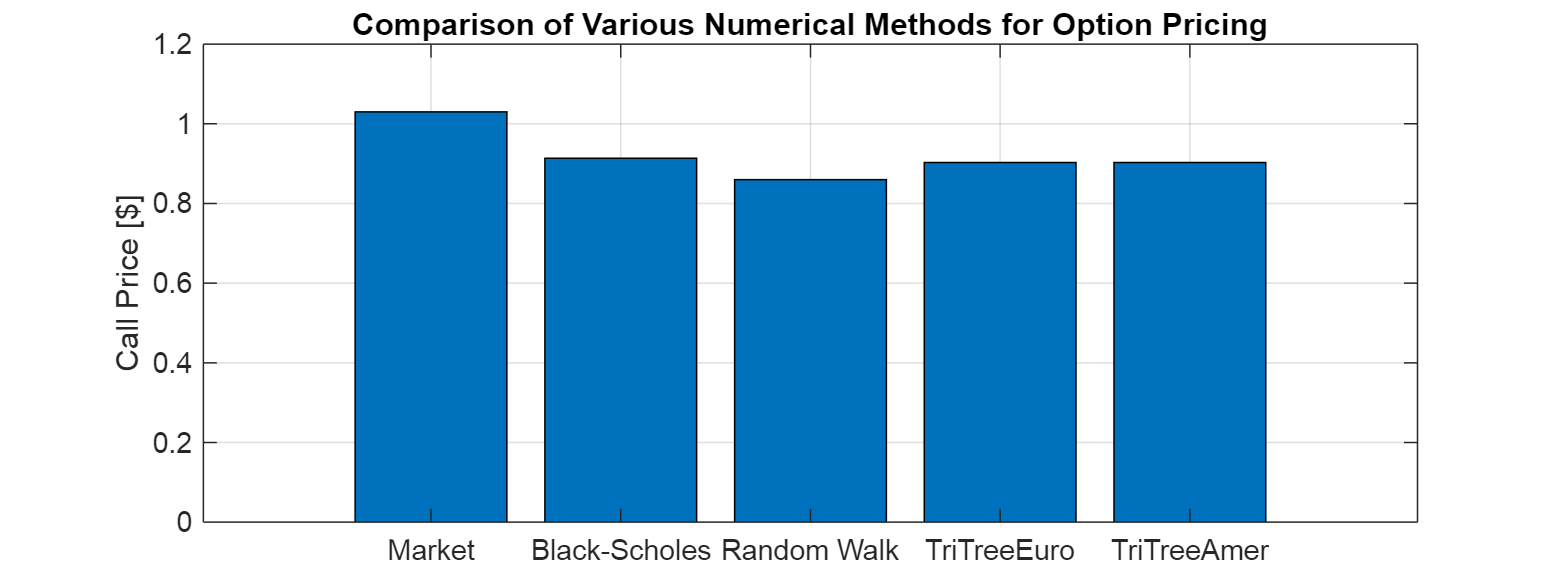


% Update on call option price by various methods
figure()
 
set(gcf,'Position',[0,0,800,300])
 
bar([C_MKT, C_BSM, C_RW, C_TRI_EURO, C_TRI_AMER])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Call Price [$]')
set(gca, 'XTickLabels', {'Market','Black-Scholes','Random Walk','TriTreeEuro','TriTreeAmer'})
 
box on
grid on

### 4. PDEs

#### (1) Construct Grid of Prices, Times, etc.

% The Grid
SMin = 25;
SMax = 100;
 
XMin = log(SMin/So)

XMin = -0.7493

XMax = log(SMax/So)

XMax = 0.6370

NX = 300;
 
% The 1+return vector
XGridPDE = linspace(XMin, XMax, NX)';
dX = (XMax - XMin) / NX

dX = 0.0046

 
% The Stock Price vector
SGridPDE = So * exp(XGridPDE);
 
% The Time vector
TMin = 0;
TMax = T

TMax = 0.1644

NT = 1000;
 
dT = (TMax - TMin) / NT

dT = 1.6438e-04

TGridPDE = linspace(TMin, TMax, NT);

#### (2) Define Option Value V(S,t)

% Option Value 
IntrinsicVPDE = max(SGridPDE - K, 0);
VPDE = NaN(NX, NT);

#### (3) Define Boundary Conditions

% Boundary Conditions
% at expiration
VPDE(:,end) = max(SGridPDE - K, 0);
 
% at the boundary SMax
VPDE(end,:) = max(SGridPDE(end) - K, 0);
 
% at the boundary SMin
VPDE(1,:) = max(SGridPDE(1) - K, 0);

#### (4) Define Key Calculation Terms

% Key Calculations
pu = (sigma55Call^2 * dT) / (2 * dX^2) + (b - sigma55Call^2/2) * dT / (2*dX)

pu = 0.1407

pm = 1 - sigma55Call^2 * dT / (dX^2)

pm = 0.7192

pd = (sigma55Call^2 * dT) / (2 * dX^2) - (b - sigma55Call^2/2) * dT / (2*dX)

pd = 0.1401

#### (5) Backward PDE Algorithm

% The PDE Algo
for n = (NT-1):-1:1
    for j = 2:NX-1
 
        % European
        %V(j,n) = (pu * VPDE(j+1,n+1) + pm * VPDE(j,n+1) + pd * VPDE(j-1,n+1)) / (1 + r*dT);
 
        % American
        VPDE(j,n) = max(IntrinsicVPDE(j), ...
                     (pu * VPDE(j+1,n+1) + pm * VPDE(j,n+1) + pd * VPDE(j-1,n+1)) / (1 + r*dT));
 
    end%for j
end%for n
 
% Find the option value at the current stock price
ICurrentPrice = find(SGridPDE >= So, 1, 'first')

ICurrentPrice = 163

C_PDE_AMER = VPDE(ICurrentPrice:ICurrentPrice)

C_PDE_AMER = 0.9506

#### (6) Results and Graphs

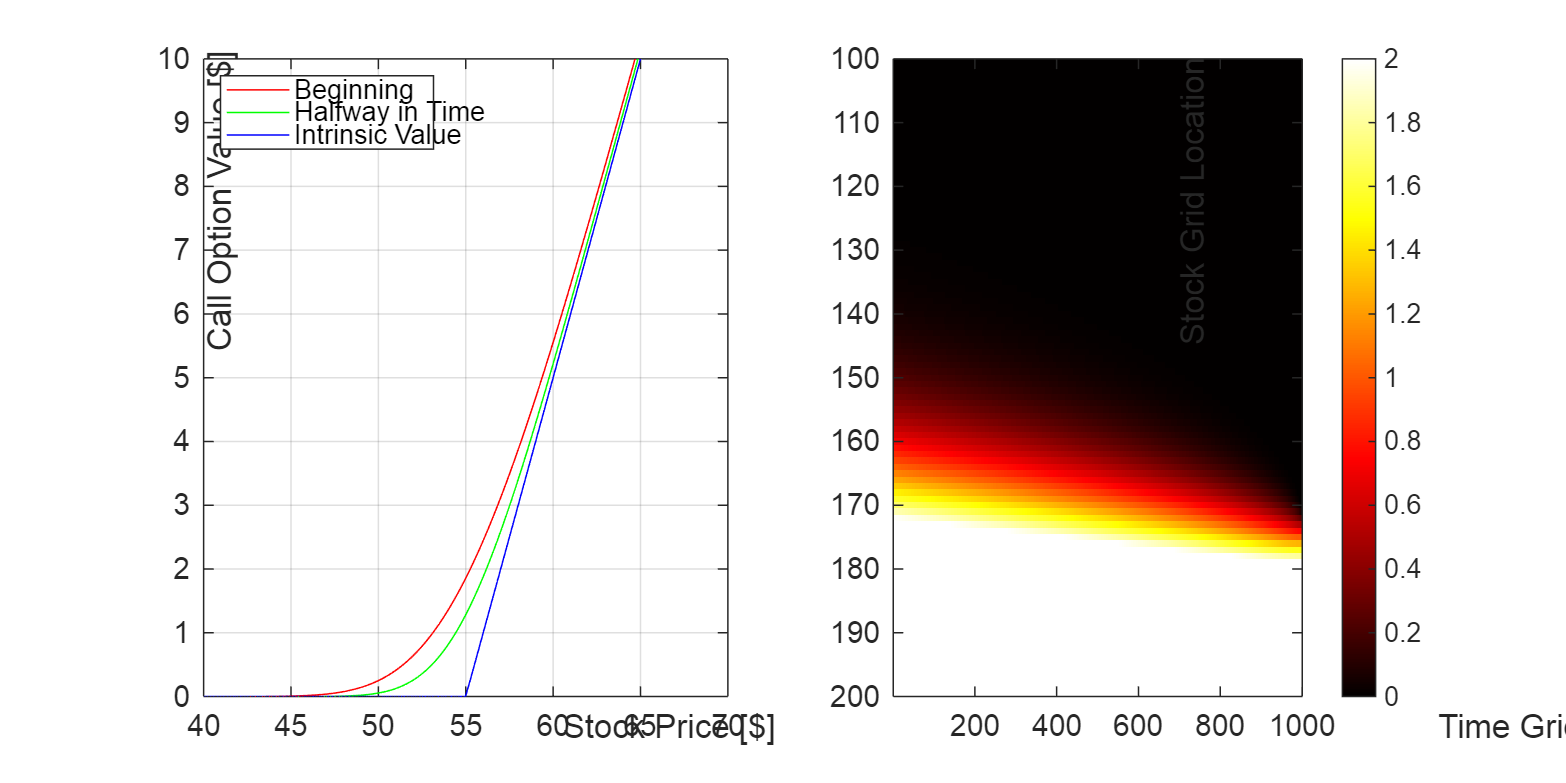

figure()
set(gcf,'Position',[0,0,1000,500])
 
subplot(1,2,1)
plot(SGridPDE, VPDE(:,1), 'r-', SGridPDE, VPDE(:,round(NT/2)), 'g-', SGridPDE, VPDE(:,NT), 'b-')
 
xlabel('Stock Price [$]')
ylabel('Call Option Value [$]')
title('American Call Option Using PDE Explicit Method')
legend({'Beginning','Halfway in Time', 'Intrinsic Value'}, 'location', 'northwest')
 
grid on
xlim([40 70])
ylim([0 10])
 
subplot(1,2,2)
%imagesc(SGridPDE, TGridPDE, VPDE)
imagesc(VPDE)
 
xlabel('Time Grid Location')
ylabel('Stock Grid Location')
colormap(hot)
ylim([100,200])
%xlim([40,70])
caxis([0,2])
colorbar

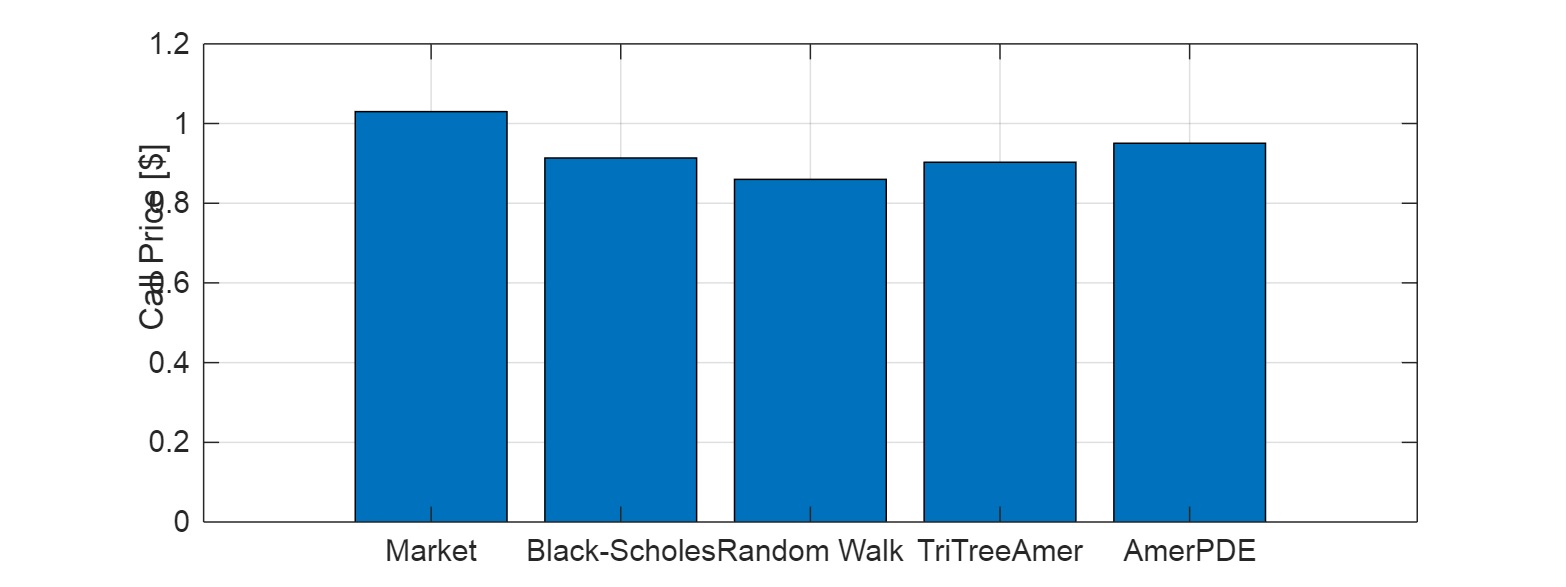


% Update on call option price by various methods
figure()
 
set(gcf,'Position',[0,0,800,300])
 
bar([C_MKT, C_BSM, C_RW, C_TRI_AMER, C_PDE_AMER])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Call Price [$]')
set(gca, 'XTickLabels', {'Market','Black-Scholes','Random Walk','TriTreeAmer','AmerPDE'})
 
box on
grid on